### Define Bridge Geometry:

global num_param_front;
global sep_of_webs;
global glue_locations;
global xc;
global yc;
global ws;
global hs;


% location of diaghragms
num_param_front = 0; % number of diaphrams
xc = [0 150 300 450 600 750 900 1050 1200]

xc =            0         150         300         450         600         750         900        1050        1200



% CROSS-SECTION:
% Lateral Location of the Changes in Cross-section across the bridge:
lc = [0 1200]

lc =            0        1200



% Location, yc (number of columns = num_param_front)
yc1 = [0 1.27 130-1.25 130;
    0 1.27 130-1.25 130]

yc1 =          0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000



% Width of Section
ws1 = [80 2*1.27 2*(5+1.27) 100;
    80 2*1.27 2*(5+1.27) 100]

ws1 =    80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000



% Height of Section
hs1 = [1.27 130-2*1.27 1.27 2*1.27;
    1.27 130-2*1.27 1.27 2*1.27]

hs1 =     1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400



sep_of_webs = 70-1.27; 
glue_locations = [1 3]

glue_locations =      1     3



interval = zeros(1201, 1);
    for i = 0:1200
        interval(i+1) = i;
    end

% interpolating input
yc = interp1(lc, yc1, interval)  % index = location along the bridge +1

yc =          0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000
         0    1.2700  128.7500  130.0000


ws = interp1(lc, ws1, interval)  % index = location along the bridge +1

ws =    80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000
   80.0000    2.5400   12.5400  100.0000


hs = interp1(lc, hs1, interval)  % index = location along the bridge +1

hs =     1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400
    1.2700  127.4600    1.2700    2.5400


### Main Code:

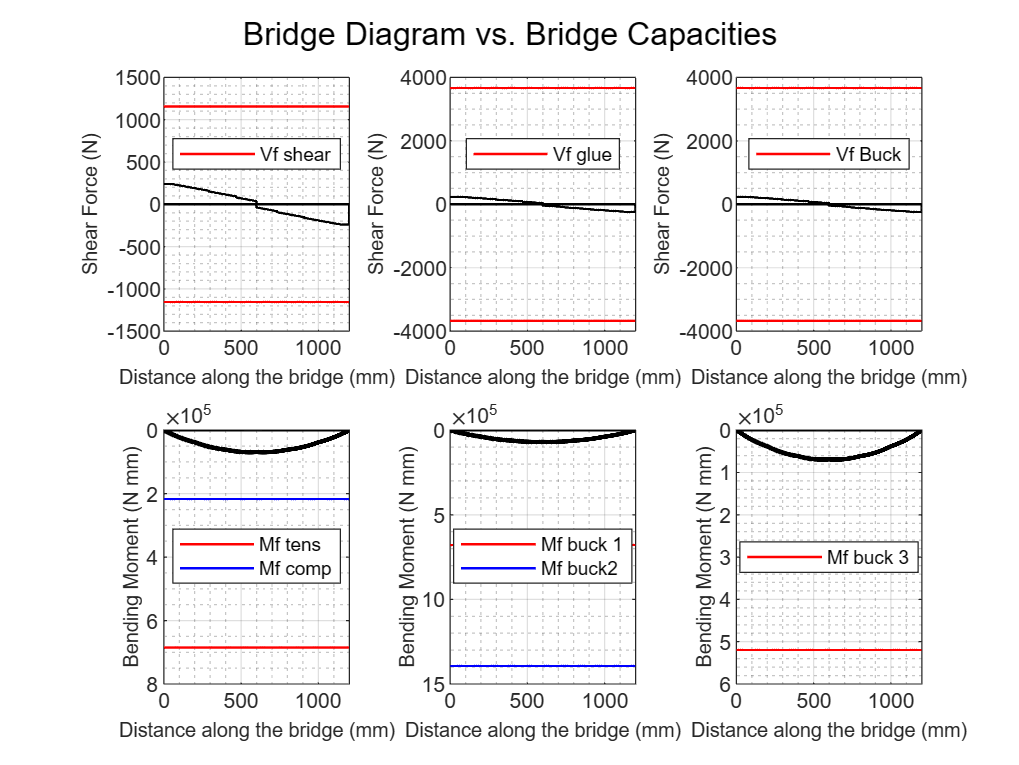

SFD_matrix = zeros(241, 1201);
BMD_matrix = zeros(241, 1201);
SFD_envelope = zeros(1, 1201);
BMD_envelope = zeros(1, 1201);

for xtrain = 1:240
    [SFD, BMD] = SFD_BMD(xtrain);
    SFD_matrix(xtrain,:) = SFD(:, 2); % still incorrect, kind of
    BMD_matrix(xtrain,:) = BMD(:, 2);
end

for dist = 0:1200
    SFD_envelope(dist+1) = max(abs(SFD_matrix(:,dist+1)));
    BMD_envelope(dist+1) = max(BMD_matrix(:,dist+1));
end

% failure calculations 
Mf_tens = zeros(1201, 1);
Mf_comp = zeros(1201, 1);
Vf_shear = zeros(1201, 1);
Vf_glue = zeros(1201, 1);
Mf_buck1 = zeros(1201, 1);
Mf_buck2 = zeros(1201, 1);
Mf_buck3 = zeros(1201, 1);
Vf_buckV = zeros(1201, 1);

FOS_tens = zeros(1201, 1);
FOS_comp = zeros(1201, 1);
FOS_flexbuck1 = zeros(1201, 1);
FOS_flexbuck2 = zeros(1201, 1);
FOS_flexbuck3= zeros(1201, 1);
FOS_shear = zeros(1201, 1);
FOS_glue = zeros(1201, 1);
FOS_shearbuck = zeros(1201, 1);
Pf = zeros(1, 1201);

for dist = 1:1201
    [Mf_tens(dist), Mf_comp(dist), Vf_shear(dist), Vf_glue(dist),Mf_buck1(dist), Mf_buck2(dist), Mf_buck3(dist), Vf_buckV(dist), FOS_tens(dist), FOS_comp(dist), FOS_flexbuck1(dist), FOS_flexbuck2(dist), FOS_flexbuck3(dist), FOS_shear(dist), FOS_glue(dist), FOS_shearbuck(dist), Pf(dist)] = master_function(dist, BMD_envelope, SFD_envelope);
end

interval = zeros(1201, 1);
    for i = 0:1200
        interval(i+1) = i;
    end

figure(1)
    subplot(231)
    plot(interval, Vf_shear(:,1), 'r-',"Linewidth", 1)
    hold on
    plot(interval, [SFD_envelope(1:600) -SFD_envelope(601:end)], 'k-', "Linewidth", 1)
    plot(interval, -Vf_shear(:,1), 'r-', "Linewidth", 1)
    plot([0,1200],[0,0], 'k-', 'Linewidth', 1)
    xlabel("Distance along the bridge (mm)",'FontSize',8)
    ylabel("Shear Force (N)",'FontSize',8)
    legend('Vf shear', 'Location', 'best')
    sgtitle("Bridge Diagram vs. Bridge Capacities")
    xlim([0 1200])

    grid on; grid minor;

    subplot(232)
    plot(interval, Vf_glue(:,1),'r-', "Linewidth", 1)
    hold on
    plot(interval, [SFD_envelope(1:600) -SFD_envelope(601:end)], 'k-', "Linewidth", 1)
    plot(interval, -Vf_glue(:,1),'r-', "Linewidth", 1)
    plot([0,1200],[0,0], 'k-', 'Linewidth', 1)
    xlabel("Distance along the bridge (mm)",'FontSize',8)
    ylabel("Shear Force (N)",'FontSize',8)
    legend('Vf glue','Location', 'best')
    xlim([0 1200])
    grid on; grid minor;

    subplot(233)
    plot(interval, Vf_glue(:,1),'r-', "Linewidth", 1)
    hold on
    plot(interval, [SFD_envelope(1:600) -SFD_envelope(601:end)], 'k-', "Linewidth", 1)
    plot(interval, -Vf_glue(:,1),'r-', "Linewidth", 1)
    plot([0,1200],[0,0], 'k-', 'Linewidth', 1)
    xlabel("Distance along the bridge (mm)",'FontSize',8)
    ylabel("Shear Force (N)",'FontSize',8)
    legend('Vf Buck','Location', 'best')
    xlim([0 1200])
    grid on; grid minor;

    subplot(2, 3, 4)
    plot(interval, -Mf_tens,'r-', "Linewidth", 1)
    hold on
    plot(interval, Mf_comp, 'b-', "Linewidth", 1)
    plot(interval, BMD_envelope, 'k-', "Linewidth", 2)
    plot([0,1200],[0,0], 'k-', 'Linewidth', 1)
    xlabel("Distance along the bridge (mm)",'FontSize',8)
    ylabel("Bending Moment (N mm)",'FontSize',8)
    legend('Mf tens', 'Mf comp','Location', 'best')
    xlim([0 1200])
    set(gca, 'Ydir', 'reverse')
    grid on; grid minor;

    subplot(2, 3, 5)
    plot(interval, Mf_buck1, 'r-', "Linewidth", 1)
    hold on
    plot(interval, Mf_buck2, 'b-', "Linewidth", 1)
    plot(interval, BMD_envelope, 'k-', "Linewidth", 2)
    plot([0,1200],[0,0], 'k-', 'Linewidth', 1)
    xlabel("Distance along the bridge (mm)",'FontSize',8)
    ylabel("Bending Moment (N mm)", 'FontSize',8)
    legend('Mf buck 1', 'Mf buck2','Location', 'best')
    set(gca, 'Ydir', 'reverse')
    xlim([0 1200])
    grid on; grid minor;

    subplot(2, 3, 6)
    plot(interval, Mf_buck3, 'r-', 'Linewidth', 1)
    hold on
    plot(interval, BMD_envelope, 'k-', "Linewidth", 2)
    plot([0,1200],[0,0], 'k-', 'Linewidth', 1)
    xlabel("Distance along the bridge (mm)",'FontSize',8)
    ylabel("Bending Moment (N mm)",'FontSize',8)
    set(gca, 'Ydir', 'reverse')
    legend('Mf buck 3','Location', 'best')
    xlim([0 1200])
    grid on; grid minor;


 FOS_tens_out = min(abs(FOS_tens))

FOS_tens_out = 9.8679

 FOS_comp_out = min(abs(FOS_comp))

FOS_comp_out = 3.1293

 FOS_flexbuck1_out = min(abs(FOS_flexbuck1))

FOS_flexbuck1_out = 9.7642

 FOS_flexbuck2_out = min(abs(FOS_flexbuck2))

FOS_flexbuck2_out = 20.0477

 FOS_flexbuck3_out = min(abs(FOS_flexbuck3))

FOS_flexbuck3_out = 7.4742

 FOS_shear_out = min(abs(FOS_shear))

FOS_shear_out = 4.8150

 FOS_glue_out = min(abs(FOS_glue))

FOS_glue_out = 15.2798

 FOS_shearbuck_out = min(abs(FOS_shearbuck))

FOS_shearbuck_out = 3.4861

 Pf_out = min(abs(Pf))

Pf_out = 1.2517e+03

### Function for Calculating SFD and BMD

function [SFD, BMD] = SFD_BMD(xtrain)
    % load calculations
    load = 400/6; %load of each wheel on the bridge, in N
    d1 = xtrain + 52;
    d2 = 176 + d1;
    d3 = 164 + d2;
    d4 = 176 + d3;
    d5 = 164 + d4;
    d6 = 176 + d5;
    
    % reaction forces
    r_b = load*(d1+d2+d3+d4+d5+d6)/1200; % moment equation (-400*x + r_b*length)
    r_a = 400 - r_b; % vertical force equilibrium
   
    % SFD
    SFDx = [0; 0; d1; d1; d2; d2; d3; d3; d4; d4; d5; d5; d6; d6; 1200; 1200];
    SFDy = [0; r_a; r_a; r_a-load; r_a-load; r_a-2*load; r_a-2*load; r_a-3*load; r_a-3*load; r_a-4*load; r_a-4*load; r_a-5*load; r_a-5*load; r_a-6*load; r_a-6*load; 0];
    
    SFD_x = [];
    SFD_y = [];
    x_value = 0;
    y_index = 1;


    for i = 1:1200
        if x_value == SFDx(y_index+1)
            y_index = y_index +2;
            SFD_x(end+1) = [x_value];
            SFD_y(end+1) = [SFDy(y_index)];
        else
            SFD_x(end+1) = [x_value];
            SFD_y(end+1) = [SFDy(y_index)];
        end

        x_value = x_value +1;
    end
    SFD_x(end+1) = [x_value];
    SFD_y(end+1) = [SFDy(end)];
   
    SFD = [SFD_x' SFD_y'];

    % BMD
    interval = zeros(1201, 1);
    for i = 0:1200
        interval(i+1) = i;
    end

    BMDx = [0; d1; d2; d3; d4; d5; d6; 1200];
    BMDy = [0; d1*SFDy(2); (d2-d1)*SFDy(4); (d3-d2)*SFDy(6); (d4-d3)*SFDy(8); (d5-d4)*SFDy(10); (d6-d5)*SFDy(12); 0];
    BMD2y = [0; sum(BMDy(1:2)); sum(BMDy(1:3)); sum(BMDy(1:4)); sum(BMDy(1:5)); sum(BMDy(1:6)); sum(BMDy(1:7)); 0];
    
    BMD3y = interp1(BMDx, BMD2y, interval);
    BMD = [interval BMD3y];
   
end

### Master function (for each section):

function [Mf_tens, Mf_comp, Vf_shear, Vf_glue, Mf_buck1, Mf_buck2, Mf_buck3, Vf_buckV, FOS_tens, FOS_comp, FOS_flexbuck1, FOS_flexbuck2, FOS_flexbuck3, FOS_shear, FOS_glue, FOS_shearbuck, Pf] = master_function(dist , BMD_envelope, SFD_envelope)
% ybar. location of centroidal axis from the bottom
global xc, global yc, global ws, global hs, global sep_of_webs

%       sum { ( base      *    height  ) +  distance from neutral axis  } / sum   (base   *    height)
ybar = (sum(ws(dist,:) .* hs(dist,:) .* (yc(dist,:) + hs(dist,:)/2) / (sum(ws(dist,:) .* hs(dist,:)))));
ybot = ybar;
ytop = yc(dist,end) + hs(dist,end) - ybar;

% I = sum {bh^3/12 + A*d}
I_matrix = (ws(dist,:) .* hs(dist,:) .* hs(dist,:) .* hs(dist,:) ./ 12) + (ws(dist,:) .* hs(dist,:) .* (yc(dist,:) + hs(dist,:)/2 - ybar).*(yc(dist,:) + hs(dist,:)/2 - ybar));
I = sum(I_matrix);

% Q at centroidal axes = A*d
Qcent = 0;
% calculating all A*d of sections below centroidal axis (will not count anything above that)
for i = 1:length(yc(dist,:))
    if yc(dist,i) + hs(dist,i) < ybar
        Qcent = Qcent + (ws(dist, i) .* hs(dist, i) .* (abs(yc(dist, i) + hs(dist, i)/2 - ybar)));
    
    elseif yc(dist,i) < ybar
        Qcent = Qcent + ((ws(dist, i) .* (ybar - yc(dist, i))) .* abs(yc(dist, i) + (ybar-yc(dist,i))/2 - ybar));
    end
end

Qglue = zeros(length(yc(dist,:))-1, 2); % number of locations with glue (assuming they connect the sections), second col indicates location

for i = 1:length(yc(dist,:))-1  % loops through all glue locations
    Qglue(i, 2) = yc(dist, i);  % stores the location (x) of glue
    j=1;
    while yc(dist, j) <= yc(dist, i) % loops through the sections under glue
        Qglue(i, 1) = Qglue(i, 1) + (ws(dist,j) .* hs(dist,j) .* (yc(dist, j) + hs(dist, j)/2 - ybar));
        j = j + 1;
    end
end

global glue_locations
maxQ = 0;
for i = 1:length(glue_locations)
    index = glue_locations(i);
    if abs(maxQ) < abs(Qglue(index,1))
        maxQ = abs(Qglue(index,1));
        r_maxQ = index;
    end
end

% STEP 4  
S_top  = BMD_envelope(dist) * ytop / I;
S_topish = BMD_envelope(dist) * (ytop-2.54)/I;
S_bot  =  -BMD_envelope(dist) * ybot / I;

T_cent =  SFD_envelope(dist) * Qcent / (I * 2.54);
T_glue =  SFD_envelope(dist) * maxQ / (I * ws(dist, index));

% STEP 5
E = 4000; % young's modulus
mu = 0.2; % Poisson's Ratio

S_tens = 30; % matboard
S_comp = 6; % matboard

T_max = 4; % matboard
T_gmax = 2; % glue

[web, idx] = max(hs(dist,:));

S_buck1 = 4*pi^2*E*(hs(dist, end))^2 / (12*(1-mu^2)*(sep_of_webs)^2);
S_buck2 = 0.425*pi^2*E*hs(dist, end)^2 / (12*(1- mu^2)*((ws(end)-sep_of_webs)/2)^2);
S_buck3 = 6*pi^2*E*(ws(dist,idx)*0.5)^2 / (12*(1-mu^2)*(yc(dist,idx+1)+hs(dist,idx+1)/2-ybar)^2);

% finding dA
for dA = 1:length([xc])-1
    if (dist <= xc(dA+1)) && (dist >= xc(dA))
        break
    end
end

temp = (ws(dist,idx)/2)^2 / (web+1.27)^2 + (ws(dist,idx)/2)^2 / (xc(dA+1)-xc(dA))^2;
T_buck = (5*pi^2*E/(12*(1-mu^2)))*temp;

% STEP 6-8
FOS_tens = S_tens/S_bot;
FOS_comp = S_comp/S_top;
FOS_flexbuck1 = S_buck1/S_top;
FOS_flexbuck2 = S_buck2/S_top;
FOS_flexbuck3 = S_buck3/S_top;
FOS_shear = T_max/T_cent;
FOS_glue  = T_gmax / T_glue;
FOS_shearbuck = T_buck / T_cent;

min_FOS = min(abs([FOS_tens; 
        FOS_comp;
        FOS_flexbuck1;
        FOS_flexbuck2;
        FOS_flexbuck3;
        FOS_shear;
        FOS_glue;
        FOS_shearbuck]));

Pf = 400 * min_FOS; % Pfail

% Vfail and Mfail
    
Mf_tens = FOS_tens * BMD_envelope(dist);
Mf_comp = FOS_comp * BMD_envelope(dist);
Mf_buck1 = FOS_flexbuck1 * BMD_envelope(dist); 
Mf_buck2 = FOS_flexbuck2 * BMD_envelope(dist);
Mf_buck3 = FOS_flexbuck3 * BMD_envelope(dist);
  
Vf_shear = FOS_shear * SFD_envelope(dist);
Vf_glue = FOS_glue * SFD_envelope(dist);        
Vf_buckV = FOS_shearbuck * SFD_envelope(dist);
    
end